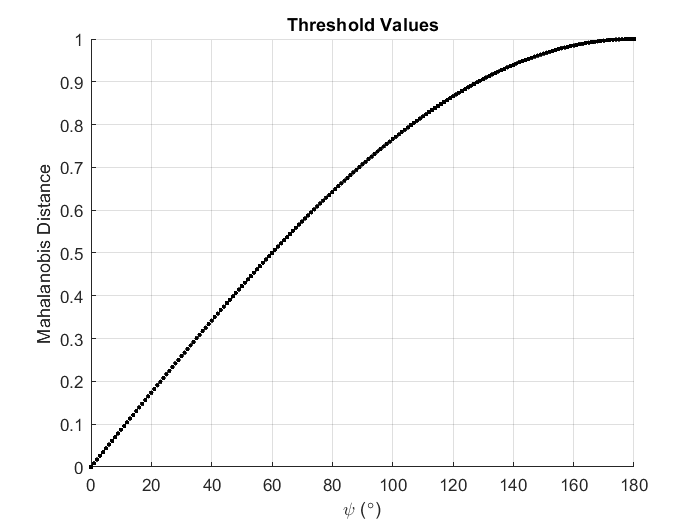

% Define Psi
psi = 0 : (1 * pi/180) : (180 * pi/180);

% Build n_fw possibilities
n_fw = zeros(3, length(psi));
for k = 1 : length(psi)
    n_fw(:,k) = [cos(psi(k)); sin(psi(k)); 0];
end

% Determine mahalaobis distance of each possibility
x_t = [1; 0; 0];
d = zeros(1, length(psi));
for k = 1 : length(psi)
    d(k) = sqrt((n_fw(:,k) - x_t)' * (n_fw(:,k) - x_t)) / 2;
end

% Plot Results
figure
hold on
plot(psi * 180/pi, d, 'k.')
title('Threshold Values')
xlabel('\psi (\circ)')
ylabel('Mahalanobis Distance')
grid on